# Simulation of systems with uncertainty

All real world systems are subject to some uncertainty, that is, we cannot know the model or the environment precisly. For example we may assume a parameter is known, but in practice our estimate will be slightly wrong. We assume a component is linear, but in practice its operation is non-linear. The enviroment (wind, temperature, etc.) is usually only known approximately and can be frequently and fast changing. In summary, we want a way of investigating how the behaviour of systems is impacted by uncertainty.

The core MATLAB functions covered in the foundational resources focus on linear systems (e.g. tf.m, ss.m, ODEs) and thus those simulations only deal with uncertainty up to a point. Users may also realise that many of the apps (car velocity, tank level, etc.) do allow some uncertainty, but in the main the simulations are using linear assumptions and thus those are relatively limited in scope.

The purpose of this file is to demonstrate how more extensive and flexible methods exist for handling uncertainty, but for now using only the very simplest examples that might appear in a first course in control. Familiarity with these tools will help users as they wish to extend their studies to more realistic scenarios in the future.

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files uncomment and run either line of the code below:**

%  For documentation in a separate window type one of these 
%        Control101
%  
%        help control101         (opens within the command window)

Source files created by J.A.Rossiter, University of Sheffield    

                

## Table of contents

- Introduction to simulation with simulink

- Open-loop simulation with non-linearity

- Open-loop simulation with non-linearity and a disturbance

- The impact of feedback

- Examples with state space models

- Case study of a non-linear tank

## 1 Introduction to simulation with simulink

This resource will assume the use of SIMULINK as the tool for defining the model and scenario. However, we will use code snippets to run the model and export the data back into MATLAB so that we can handle plotting and scenario variations in a simple and transparent way.

The core point to note is that simple simulink files will pull in the relevant parameter values directly from the active workspace (e.g. command window or livescript file), so it is sufficient to define those parameter values directly in a short code snippet. The simulink file can be 'run' using the ***sim*** command, and any outputs sent to an appropriate variable for later plotting and/or analysis. The following sections will give a number of simple examples.

**Remark**: Other methods exist for pushing values into simulink and are beyond the remit of this resource.

## 2 Open-loop simulation with non-linearity

The first case deals with non-linearity as the simulation of a non-linear system requires numerical integration which is non-simple; SIMULINK will deal with the subtleties for you so the beginner need to not worry about this. The first example is ***openloopmodel_saturation_control101*** which is an open-loop simulation, but where the output is saturated (see Figure 1). This example collects the target from the a simple step input, uses this as the input to a simple 1st order model, scales by a gain, saturates and then sends the output back to the workspace.

**Figure 1**: Screen capture of the simulink file ***openloopmodel_saturation_control101.slx***

**Remark*****: ***Open the file in simulink and double click on any of the components to see what detail and parameters are assumed. e.g.*** open openloopmodel_saturation_control101.slx***

To run the file, enter the required model and environment parameters (the code snippet below shows you what these are) and then use the command:

***out=sim("openloopmodel_saturation_control101.slx");***

Users will note how the output stops changing when it reaches the value of '2' dictated by the saturation block. Try changing the parameters in the code snippet below and exploring how the behaviour changes.

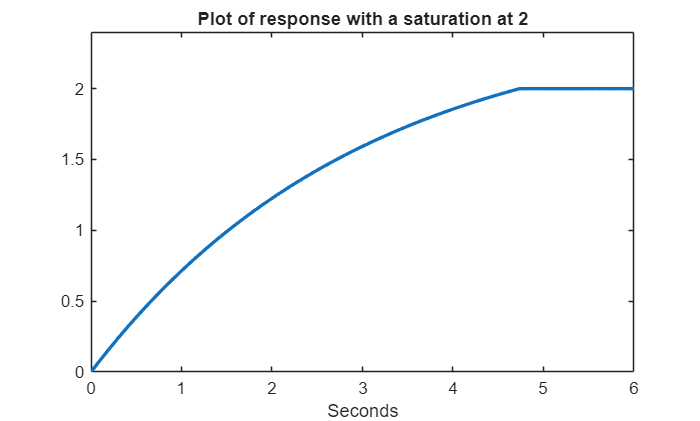

% Define the data needed in the simulation
target=3;
umax=2; % Saturation limits
umin=-1;
gain =1.2;  % This is K
stoptime=6;
den=[3,1]; % Model parameters    num=C, den = [T,1]
num=0.7;

% Run simlink file
out=sim("openloopmodel_saturation_control101.slx");

% extract data for plotting and analysis
ydata = getElement(out.yout,'Out 1');
y=ydata.Values.Data;
t=ydata.Values.Time;
plot(t,y,'LineWidth',2)
ylim([0,umax*1.2])
title(['Plot of response with a saturation at ',num2str(umax)])
xlabel('Seconds')


%print(['-sopenloopmodel_saturation_control101'],'-djpeg',['openloopmodel_saturation_control101.jpg'])

**Remark**: To see results without the saturation block, set umax and umin to large numbers.  Obviously you can change any parameters in the code snippets below as required for your own investigations.

## 3 Open-loop simulation with non-linearity and a disturbance

The second case details adds an external (assumed unknown) disturbance signal to the scenario. The differences between Figure 1 and 2 should be obvious.

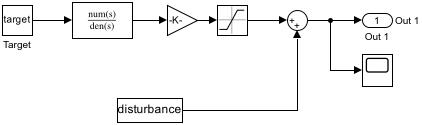

**Figure 2**: Screen capture of the simulink file ***openloopmodel_saturationb_control101.slx***

To run the file, enter the required model and environment parameters (the code snippet below shows you what these are) and then use the command:

***out=sim("openloopmodel_saturationb_control101.slx");***

Here however we are particularly interested in investigating the impact of the disturbance comparing behaviour with and without this signal.

### 3.1 Disturbance uncertainty

The code snippet below illustrates how an investigation into disturbance uncertainty could be performed. Users can change the parameters and use 'run section' to investigate different scenarios.

disp('Section 2 below')

Section 2 below


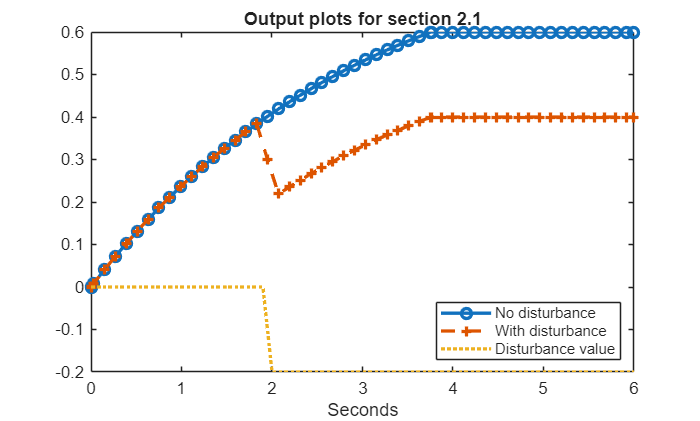

%define parameters
target=1;
umax=0.6; % saturation limits
umin=-1;
gain =1.2;
stoptime=6;
den=[3 1]; deltaden=[0.2 1];% Model parameters and uncertainty
num=0.7; deltanum=0.1;

%disturbance profile
disturbancevec=[zeros(1,20),-ones(1,41)*0.2];
timevec=linspace(0,stoptime,61);
disturbance = [timevec',disturbancevec'];

% Run simlink files with and without the disturbance
out1=sim("openloopmodel_saturation_control101.slx");
out2=sim("openloopmodel_saturationb_control101.slx");

% extract data for plotting and analysis
ydata1 = getElement(out1.yout,'Out 1');
y1=ydata1.Values.Data;
t1=ydata1.Values.Time;
ydata2 = getElement(out2.yout,'Out 1');
y2=ydata2.Values.Data;
t2=ydata2.Values.Time;

plot(t1,y1,'-o',t2,y2,'--+',timevec,disturbancevec,':','Linewidth',2)
legend('No disturbance','With disturbance','Disturbance value','Location','southeast')
title('Output plots for section 2.1')
xlabel('Seconds')

%print(['-sopenloopmodel_saturationb_control101'],'-djpeg',['openloopmodel_saturationb_control101.jpg'])

### **3.2 Adding model or parameter uncertainty**

It is relatively straightforward to add simple parameter uncertainty into the investigation by changing the model parameters before calling the simulation, The code snippet below gives a simple illustration of this.

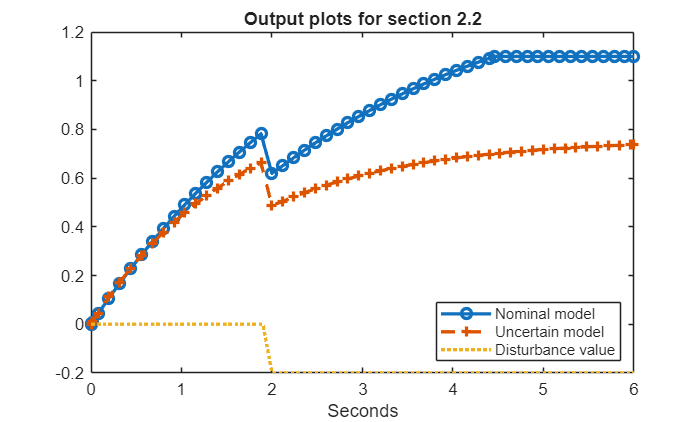

% update some parameters
target=2;
umax=1.3; % saturation limits

% Run simlink files with and without the disturbance and for different models
out1=sim("openloopmodel_saturationb_control101.slx");  % No parameter uncertainty
den=den+deltaden; num=num+deltanum;   % change parameters
out2=sim("openloopmodel_saturationb_control101.slx");  % with parameter uncertainty

% extract data for plotting and analysis
ydata1 = getElement(out1.yout,'Out 1');
y1=ydata1.Values.Data;
t1=ydata1.Values.Time;
ydata2 = getElement(out2.yout,'Out 1');
y2=ydata2.Values.Data;
t2=ydata2.Values.Time;

plot(t1,y1,'-o',t2,y2,'--+',timevec,disturbancevec,':','Linewidth',2)
legend('Nominal model','Uncertain model','Disturbance value','Location','southeast')
xlabel('Seconds')
title('Output plots for section 2.2')

### **2.3 Student activity** 

Try modifying the simulink files to investigate different structures/scenarios, for example putting the disturbance in front of the transfer function block. You would need to make a copy of the simulink file in your own folder, rename and modify the code above to call your file.

## 4 The impact of feedback

Feedback loops can be added very easily in simulink and thus one can investigate the impact of these on behaviour, with and without uncertainty and non-linearity. This is shown in Figure 3. In this section we will overlay open and closed-loop responses os that users can analyse the impact of uncertainty (quantitavely); this serves as one motivation for feedback in the longer term, that is, to reduce the impact of uncertainty.

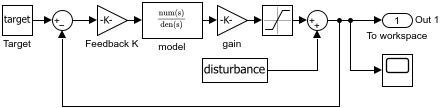

**Figure 3**: Screen capture of the simulink file ***closedloopmodel_saturation_control101.slx***

The plots are given as follows:

- The first assumes no uncertainty and simply compares open and closed-loop. The two are different.

- The second looks at the impact of disturbances on open and closed-loop. Itis noted how the closed-loop response deviates less.

- The third introduces some parameter uncertainty (equivalently parameter changes). Again it is seem that the closed-loop responses deviate less.

- Plot 4 shows only open-loop plots in the different scenarios and plot 5 the corresponding closed-loop plots. Again it is clear that in simple terms, deviations are less in the closed-loop.

%print(['-sclosedloopmodel_saturation_control101'],'-djpeg',['closedloopmodel_saturation_control101.jpg'])
disp('Section 3')

Section 3


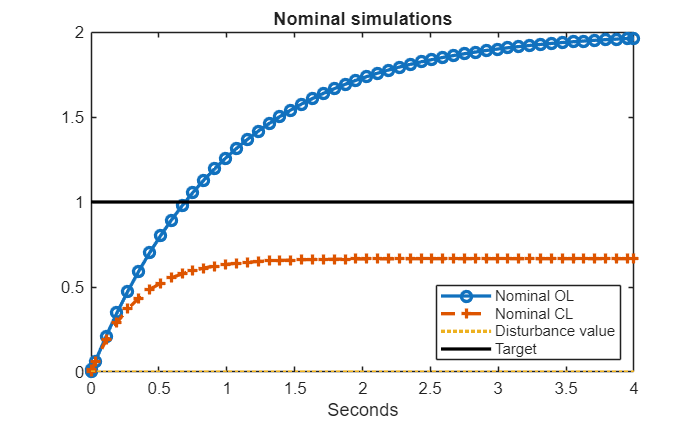


% parameter values
target=1;
umax=3; % saturation limits
umin=-1;
gain =2;
stoptime=4;
den=[1 1]; deltaden=[0.2 0]; % Model parameters
num=1; deltanum=[0.2];
Kfeedback=1;

%disturbance profile
disturbancevec=[zeros(1,20),ones(1,41)*0.2];
timevec=linspace(0,stoptime,61);
disturbance = [timevec',0*disturbancevec'];

% Open- and closed-loop simulation with nominal values and no disturbance
opennominal=sim("openloopmodel_saturation_control101.slx"); % with disturbance
closednominal=sim("closedloopmodel_saturation_control101.slx"); % with disturbance
yopennom = getElement(opennominal.yout,'Out 1');
yclosednom = getElement(closednominal.yout,'Out 1');

plot(yopennom.Values.Time,yopennom.Values.Data,'-o',...
    yclosednom.Values.Time,yclosednom.Values.Data,'--+',...
    timevec,0*disturbancevec,':',...
    [0,stoptime],[target, target],'k-','Linewidth',2)
legend('Nominal OL','Nominal CL','Disturbance value','Target',...
    'Location','Southeast')
title('Nominal simulations')
xlabel('Seconds')


% Open- and closed-loop simulation with nominal values and a disturbance
disturbance = [timevec',disturbancevec'];
opendist=sim("openloopmodel_saturationb_control101.slx"); % with disturbance
closeddist=sim("closedloopmodel_saturation_control101.slx"); % with disturbance
yopendist = getElement(opendist.yout,'Out 1');
ycloseddist = getElement(closeddist.yout,'Out 1');
xlabel('Seconds')

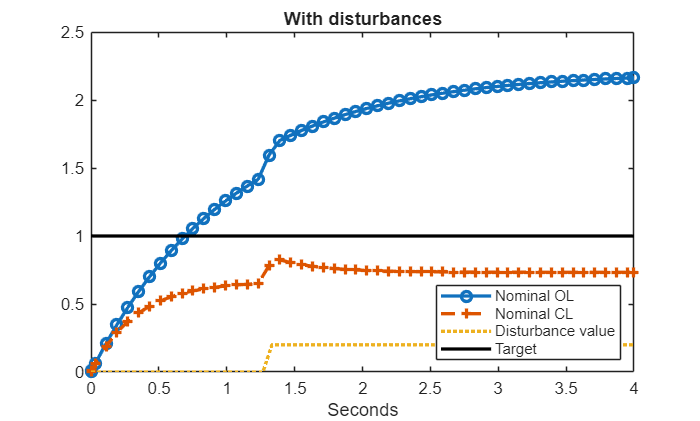


plot(yopendist.Values.Time,yopendist.Values.Data,'-o',...
    ycloseddist.Values.Time,ycloseddist.Values.Data,'--+',...
    timevec,disturbancevec,':',...
    [0,stoptime],[target, target],'k-','Linewidth',2)
legend('Nominal OL','Nominal CL','Disturbance value','Target',...
    'Location','Southeast')
title('With disturbances')
xlabel('Seconds')

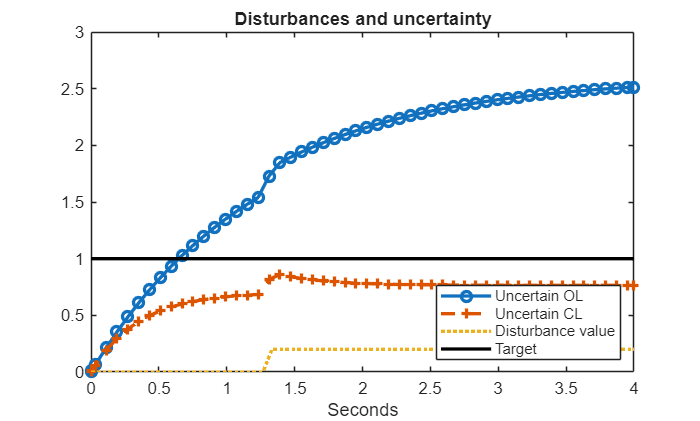


% Open- and closed-loop simulation with different model parameters
den=den+deltaden; num=num+deltanum;   % change parameters
openuncert=sim("openloopmodel_saturationb_control101.slx"); % with disturbance
closeduncert=sim("closedloopmodel_saturation_control101.slx"); % with disturbance
yopenunc = getElement(openuncert.yout,'Out 1');
yclosedunc = getElement(closeduncert.yout,'Out 1');

plot(yopenunc.Values.Time,yopenunc.Values.Data,'-o',...
    yclosedunc.Values.Time,yclosedunc.Values.Data,'--+',...
    timevec,disturbancevec,':',...
    [0,stoptime],[target, target],'k-','Linewidth',2)
legend('Uncertain OL','Uncertain CL','Disturbance value','Target',...
    'Location','Southeast')
title('Disturbances and uncertainty')
xlabel('Seconds')

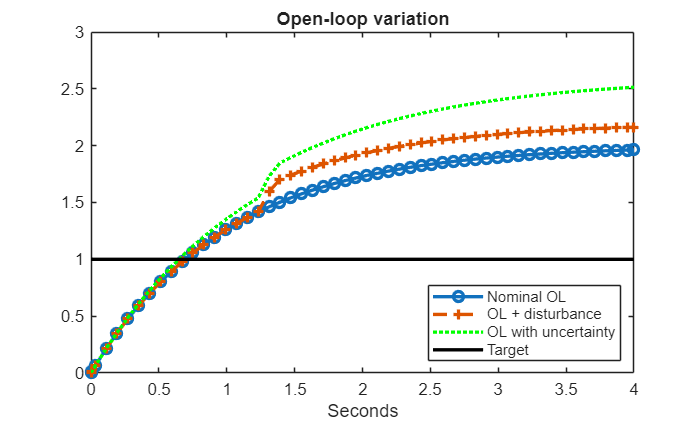


% Compare open-loop responses
plot(yopennom.Values.Time,yopennom.Values.Data,'-o',...
    yopendist.Values.Time,yopendist.Values.Data,'--+',...
    yopenunc.Values.Time,yopenunc.Values.Data,'g:',...
    [0,stoptime],[target, target],'k-','Linewidth',2)
legend('Nominal OL','OL + disturbance','OL with uncertainty','Target',...
    'Location','Southeast')
title('Open-loop variation')
xlabel('Seconds')

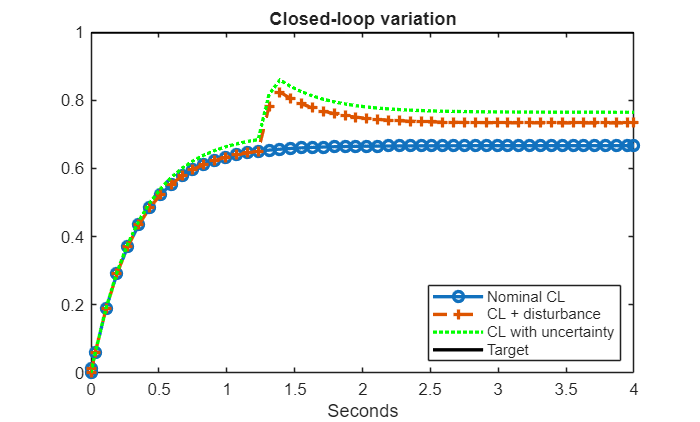


% Compare closed-loop responses
plot(yclosednom.Values.Time,yclosednom.Values.Data,'-o',...
    ycloseddist.Values.Time,ycloseddist.Values.Data,'--+',...
    yclosedunc.Values.Time,yclosedunc.Values.Data,'g:',...
    [0,stoptime],[target, target],'k-','Linewidth',2)
legend('Nominal CL','CL + disturbance','CL with uncertainty','Target',...
    'Location','Southeast')
title('Closed-loop variation')
xlabel('Seconds')

### Student activity 

The code snippet above shows a single example. Users can easily change the transfer function models, choice of feedback, saturation limits and disturbance and thus investigate to what extent the simplistic observations are more generic. You can also change the feedback block into a transfer function block to include more complicated feedback laws.  Move the saturation to the controller output to investigate input saturation.

## 5 Examples with state space models

This section illustrates that simulink models can work equally well with state space representations and adds in a few other examples of usage to extend students awareness.

### 5.1 State space model

A 1st order differential model takes the form


$$\frac{\mathrm{dx}}{\mathrm{dt}}+a\;x=b\;u$$


A state space model takes the form


$$\dot{x} =A\;x+B\;u;\;y=C\;x+D\;u$$


and thus is defined by parameters *A,B,C,D*.

It can be seen that these two are equivalent if we assume *y=x* and 


$$a=-A,b=B,C=1,D=0\ldotp$$


Simulink contains a state space block so we can use this to capture a simple 1st order differential model by assigning the parameters appropriately.

**Remark**: The state space block allows the easy insertion of a non-zero initial condition *x(0)*. Also, while this example uses only a 1st order example, higher order examples can also be expressed in state space form (see resources on state space models). 

### 5.2 Including parallel simulations in the same simulink file

It may be convenient to include multiple models within the same file and this is easy to do as shown in Figure 4 below which contains the open-loop and closed-loop simulations side by side.

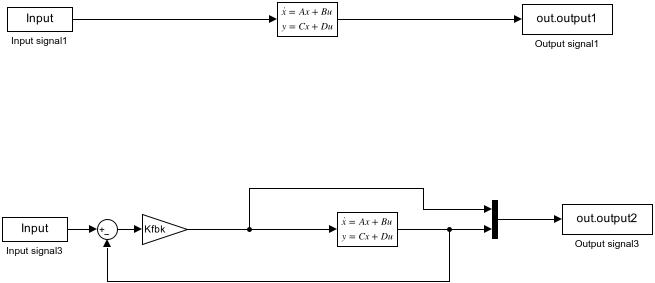

**Figure 4**: Screen capture of the simulink file ***open_and_closed_ss_simulink_control101.slx***

Consider the 1st order ODE:


$$\frac{\mathrm{dx}}{\mathrm{dt}}+3x=2u;y=x\;\;\Rightarrow \;A=-3,B=2,C=1,D=0$$


The definition of the required data values, how to run the simulation and the plotting of the results is shown in the code snippet here. Specifically, this code investigates the impact of changes in the proportional feedback gain value.

%print(['-sopen_and_closed_ss_simulink_control101'],'-djpeg',['open_and_closed_ss_simulink_control101.jpg'])

disp('Section 5 below')

Section 5 below


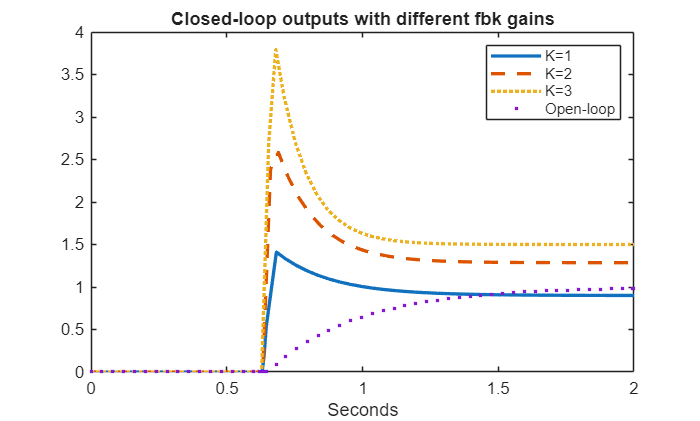


% State space model data
target=1;
A=[-3]; B=[1];C=[2]; D=0;
x0 = 0;
stoptime=2;
Kfbk=1;

%Input profile 
u=[zeros(1,20),ones(1,41)*1.5];
timevec=linspace(0,stoptime,61);
Input = [timevec',u'];

% Open- and closed-loop simulation with nominal values 
opennominal=sim("open_and_closed_ss_simulink_control101.slx"); % with disturbance
% Open- and closed-loop simulation with different K
Kfbk=2; opennominal2=sim("open_and_closed_ss_simulink_control101.slx"); % with disturbance
Kfbk=3; opennominal3=sim("open_and_closed_ss_simulink_control101.slx"); % with disturbance

% plot the results
plot(opennominal.tout,opennominal.output2(:,1).Data(:,1),'-',...
    opennominal2.tout,opennominal2.output2.Data(:,1),'--',...
    opennominal3.tout,opennominal3.output2.Data(:,1),':', ...
    opennominal.tout,opennominal.output1(:,1).Data(:,1),'.','Linewidth',2)
legend('K=1','K=2','K=3','Open-loop','Location','Northeast')
title('Closed-loop outputs with different fbk gains')
xlabel('Seconds')

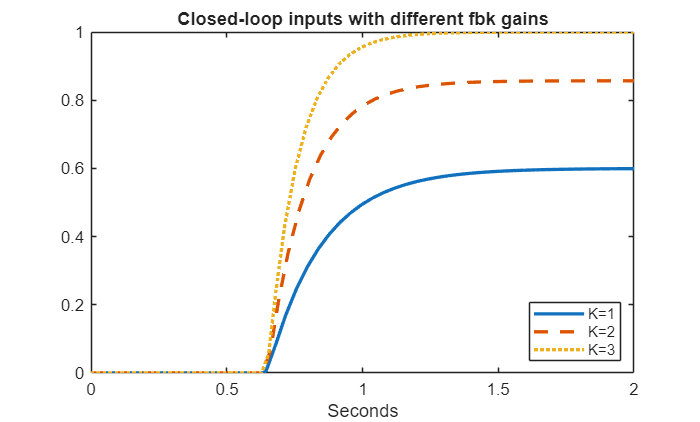


plot(opennominal.tout,opennominal.output2(:,1).Data(:,2),'-',...
    opennominal2.tout,opennominal2.output2.Data(:,2),'--',...
    opennominal3.tout,opennominal3.output2.Data(:,2),':','Linewidth',2)
legend('K=1','K=2','K=3','Location','Southeast')
title('Closed-loop inputs with different fbk gains')
xlabel('Seconds')

The figures clearly show how the time constant (closed-loop poles) varies with the choice of feedback gain and also how the input changes.

**Student activity:** Experiment with different model parameter choices and feedback gains

### 5.3 Adding non-linearity to the state space model simulations

A really big advantage of Simulink is that it naturally allows the modelling of non-linearities and thus one can investigate scenarios where simple analytic solutions do not exist. In this case a simple non-linearity is added to a model for illustration purposes, in essence a gain which has an exponential characteristic, so is not fixed. The code compares the behaviour of the 'linear and non-linear' systems in both open and closed-loop. For convenience, the 4 different models are captured in a single Simulink file as shown in Figure 4.

Of particular interest here the user will note that the variation in closed-loop performance is less than that in the open-loop.

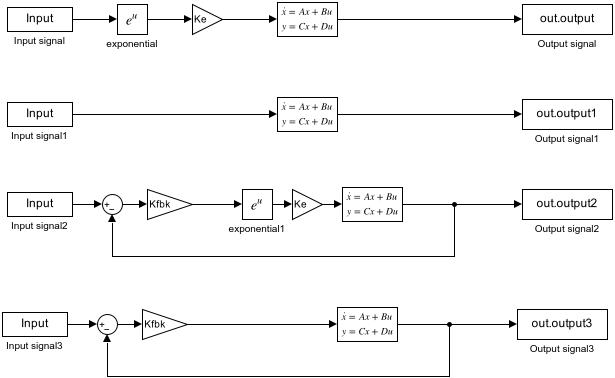

**Figure 5**: Screen capture of the simulink file ***open_and_closed_ss_simulink_nl_control101.slx***

%print(['-sopen_and_closed_ss_simulink_nl_control101'],'-djpeg',['open_and_closed_ss_simulink_nl_control101.jpg'])

disp('Section 5.2 below')

Section 5.2 below


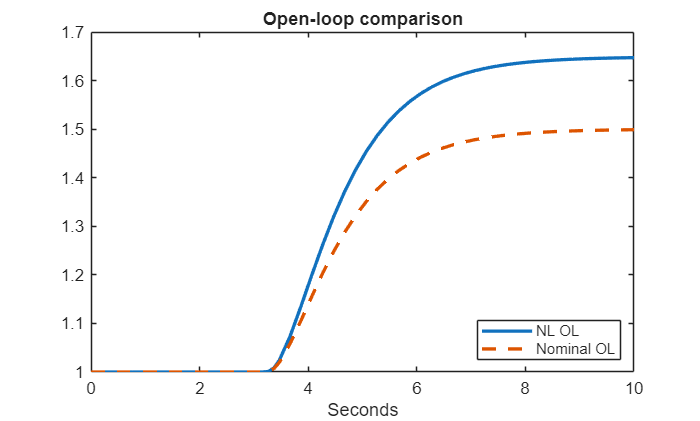

% Model data and linearisation point
target=1;
A=[-3 -2;1 0]; B=[1;0];C=[0 2]; D=0;
uss = 1; x0 = -inv(A)*B;
Ke=exp(-1);
stoptime=10;
Kfbk=1;

%Input profile 
u=[ones(1,20),ones(1,41)*1.5];
timevec=linspace(0,stoptime,61);
Input = [timevec',u'];

% Open- and closed-loop simulation with nominal values and no disturbance
opennominal=sim("open_and_closed_ss_simulink_nl_control101.slx"); % with disturbance

% plot the results
plot(opennominal.tout,opennominal.output.Data,'-',...
    opennominal.tout,opennominal.output1.Data,'--','Linewidth',2)
legend('NL OL','Nominal OL','Location','Southeast')
title('Open-loop comparison')
xlabel('Seconds')

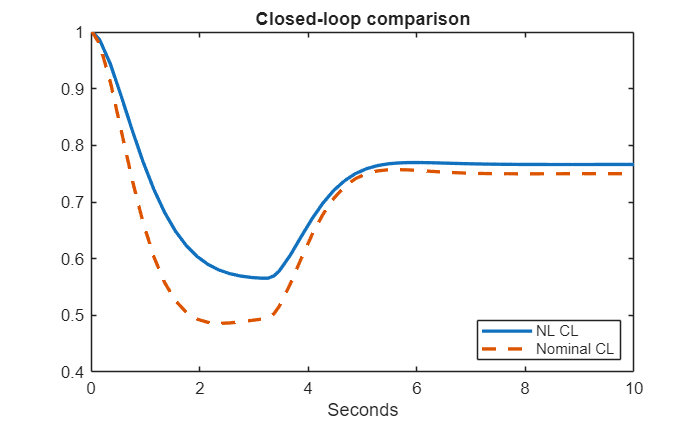


plot(opennominal.tout,opennominal.output2.Data,'-',...
    opennominal.tout,opennominal.output3.Data,'--','Linewidth',2)
legend('NL CL','Nominal CL','Location','Southeast')
title('Closed-loop comparison')
xlabel('Seconds')

## 6 Case study of a non-linear tank

This section reviews a case study that is included elsewhere in the toolbox under virtual laboratories.

***nonlinear_tank_behaviour_control101.mlapp***, 

***nonlinear_tank_system_control.mlapp***.

Some aspects are repeated here for reader convenience but for more detail read the original resources.

The file below performs the simulation of a tank model with a non-linear component describing the exit flow; this is overlaid with the linearised model at the operating point (initial condition).

### 6.1 Model parameters

As the model is more authentic and thus more complicated, there are a large number of model parameters to define.

blocksize = 0.2;  % size of blockage as percentage
qstep = 0.01;     % change in inflow compared to steady-state
endtime=2400;     % simulation run time
blockagetime=600; % time that blockage introduced
qchangetime = 200; % time that change in flow introduced

% Model parameters needed by simulink file
rho=1000;    % water density
g=10;        % gravity
A=2;  Ai=1/A;  % tank area
Ae = A;  Aie = 1/Ae;  % estimated tank area
R=10^4;      % constant needed to determine outflow
Re = R;  % estimated R
C=sqrt(rho*g)/R;
Ctemp = C*(1-blocksize);  % Increase R during blockage which reduces outflow
hss = 0.5;
qss = C*sqrt(hss);

% Linear model
Ce=sqrt(rho*g)/Re;
hsse = 0.5;
qsse = Ce*sqrt(hsse);
Cl=Ce/(2*sqrt(hsse));

### 6.2 Simulation parameters

Next it is necessary to define the required responses, target changes,  disturbances and so forth. As one of the files details with feedback, we also need to define the PI control law parameters.

Readers may note that this simulation does also allow for input saturation and the impact is clear by making suitable choices below.

% Simulation parameters
Initial_target = hss;
Targetchange = 0.4;
Targetchangetime = 200;
Noise=[];
Noise(:,1) = [0:endtime]';
Noise(:,2)= 0*randn(1,endtime+1)'/100;    % magnitude of measurement noise
disturbanceflowtime=800;
disturbanceflow=0.00;
switchpidtime=0;   % With or without anti-windup
switchpid=1;       % no anti windup

% Model parameters needed by simulink file
Ce=sqrt(rho*g)/Re;
Dumax = 0.002;    % rate limits on input: 
Dumin = -0.002;
umax = 0.009;      % absolute limits on the input
umin = -0.01;
Cl=Ce/(2*sqrt(Initial_target));

% PI compensator
Kp = Cl;
Ki = Cl^2/A;

% Closed-loop behaviour with linearised model
G=tf(1,[A,Cl]);
M=tf([Kp,Ki],[1 0]);
[y,t]=step(feedback(G*M,1));
u=step(feedback(M,G),t);

#### 6.3 Open and closed-loop simulation

The next bit of code uses  the simulink files and produces the simulated behaviour, for both the linearised model and using the full NL model.

- The disturbance is defined in section 6.2 and is currently set at ZERO.

- The output measurement noise is defined in section 6.2 and is currently set at ZERO.

- The system blockage (a parameter change) is defined in section 6.1 and is currently set at 20%.

It will be clear again that introducing freedback reduces significantly the differences in behaviour between the linear and non-linear systems. However including saturation means that aspect could dominate any transient behaviour.

disp('Section 6 below')

Section 6 below


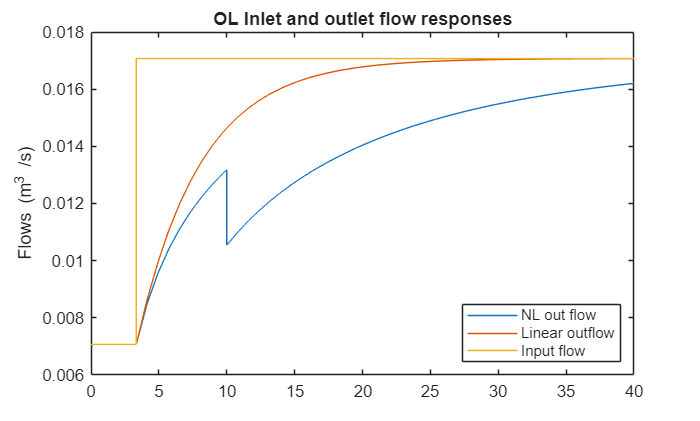


% Open-loop simulation 
sim("non_linear_tank_system_control101_2023.slx");
tt=nonlineardata.time;
yy = nonlineardata.signals.values; % stored in order as shown in Figure 1.3
yl = lineardata.signals.values; % stored in order as shown in Figure 1.3

% Closed-loop simulation 
sim("non_linear_tank_system_fbk_control101_2023.slx");
ttc=nonlineardata.time;
yyc = nonlineardata.signals.values; % stored in order as shown in Figure 2

% Plotting
plot(tt/60,[yy(:,[2]),yl(:,2),yy(:,4)*blocksize]);
legend('NL depth','Linear depth','Blockage','Location','southeast')
ylabel('Depth (m)')
xlabel('Time (min)')
title('OL Depth responses')

plot(tt/60,[yy(:,[3]),yl(:,[3])],tt/60,[yy(:,[1])]);
legend('NL out flow','Linear outflow','Input flow','Location','southeast')
title('OL Inlet and outlet flow responses')
ylabel('Flows (m^3 /s)')

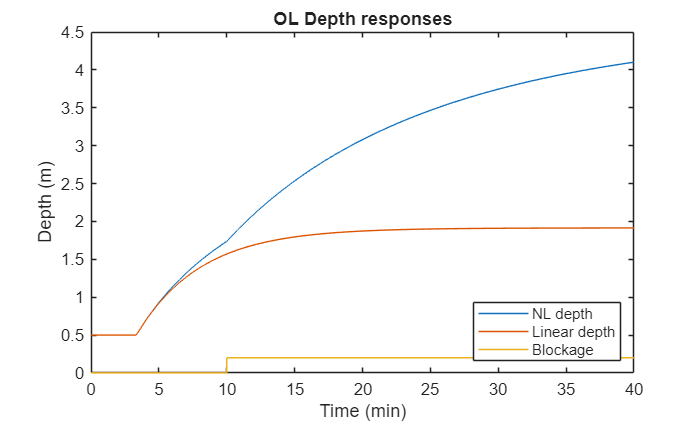


plot(ttc/60,[yyc(:,[5])],(t+Targetchangetime)/60,y*Targetchange+hss,...
    ttc/60,yyc(:,4)*blocksize,ttc/60,[yyc(:,[1])]);

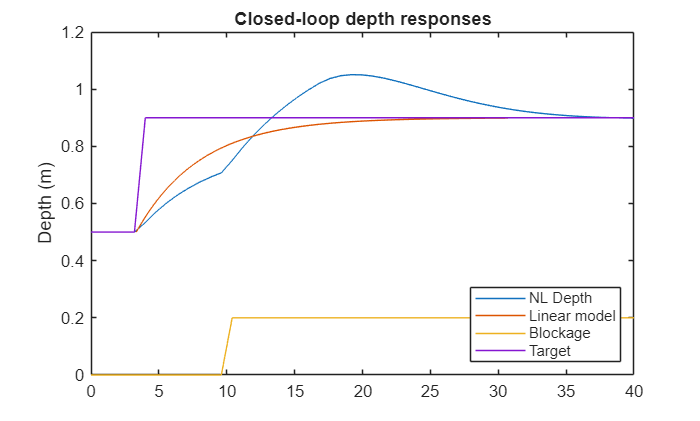

legend('NL Depth','Linear model','Blockage','Target','Location','southeast')
title('Closed-loop depth responses')
ylabel('Depth (m)')

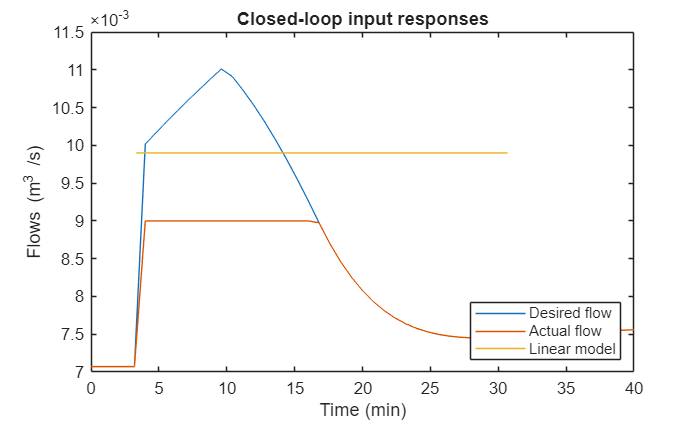


plot(ttc/60,[yyc(:,[2]),],ttc/60,[yyc(:,[3]),],(t+Targetchangetime)/60,u*Targetchange+qss)
legend('Desired flow','Actual flow','Linear model','Location','southeast')
ylabel('Flows (m^3 /s)')
xlabel('Time (min)')
title('Closed-loop input responses')